# Aula 12 - Compensadores em Frequência


$$G{\left(s\right)}=\frac{0.1}{s\left(3s+1\right)\left(2s+1\right)}$$


### a) Projete um compensador de avanço para que $K_v=0.5$ e $MF=40º$

A fórmula do compensador de avanço é $G_c=K_c \frac{1+sT}{1+\alpha sT}$, para $\alpha<1$.

PASSO A PASSO:

1- Obter $K_c$ para atender ao erro estacionário.


$$K_v=\lim_{s\rightarrow0}K_c s G(s)=0.5$$


clear
Kc=0.5/0.1

Kc = 5

2- Obter MF para $G_c=K_c$

s=tf('s');
G=0.1/(s*(3*s+1)*(2*s+1))

G =
 
         0.1
  -----------------
  6 s^3 + 5 s^2 + s
 
Continuous-time transfer function.



[Gm,Pm]=margin(Kc*G)

Gm = 1.6667

Pm = 15.1601

3- Obter o avanço necessário

$\phi_m=40º-MF_{antiga}+\Delta$, sendo $\Delta=5º \tilde\ 10º$ (para esse exercicio é preciso um $\Delta=37º$, sendo que 15º é o limite recomendado pelo Ogata)

phi=40-Pm+37

phi = 61.8399

4- Obter $\alpha$


$$sin(\phi_m)=\frac{1-\alpha}{1+\alpha} \rightarrow \alpha=\frac{1-sin(\phi_m)}{1+sin(\phi_m)}$$


alpha=(1-sind(phi))/(1+sind(phi))

alpha = 0.0629

5- Obter a nova frequência de cruzamento onde $|G(j\omega)|_{dB}=-20log(\frac{1}{\sqrt{\alpha}})$

modulo=-20*log10(1/sqrt(alpha))

modulo = -12.0130

[mag,phase,wout] = bode(Kc*G);
wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 0.6086

6- Obter T


$$\omega_c=\frac{1}{\sqrt{\alpha}T}$$


T=1/(sqrt(alpha)*wc)

T = 6.5509

TESTE

Gc=Kc*(1+s*T)/(1+alpha*s*T)

Gc =
 
  32.75 s + 5
  ------------
  0.4121 s + 1
 
Continuous-time transfer function.



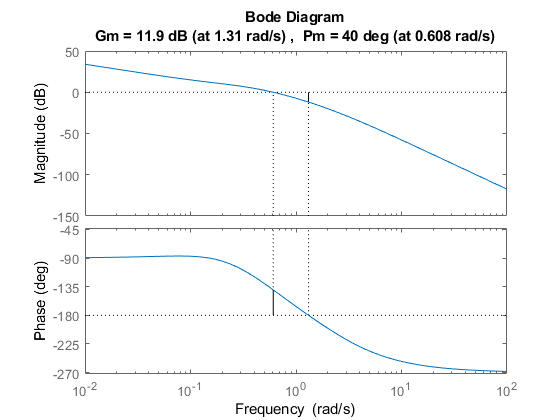

margin(Gc*G)

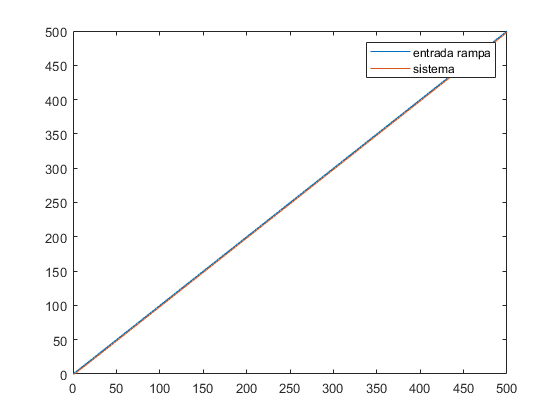

t=linspace(0,500,500);
R=step(1/s,t);
plot(t,R)
hold on
Y=step(1/s*feedback(G*Gc,1),t);
plot(t,Y)
hold off
legend('entrada rampa', 'sistema')
axis([0 500 0 500])

Kv=1/(max(R)-max(Y))

Kv = 0.5000

O controlador consegue alcançar a margem de fase de 40º, mas para isso é necessário colocar uma "gordura" de 37º, muit além do limite de 15º recomendado pelo Ogata.

### b) Projete um compensador de atraso paras as mesmas especificações.

A fórmula do compensador de atraso é $G_c=K_c \frac{1+sT}{1+\beta sT}$, para $\beta<1$.

PASSO A PASSO:

1- Obter $K_c$ para atender ao erro estacionário.


$$K_v=\lim_{s\rightarrow0}K_c s G(s)=0.5$$


clear
close all
Kc=0.5/0.1

Kc = 5

2- Obter MF e $\omega_c$ para $G_c=K_c$

s=tf('s');
G=0.1/(s*(3*s+1)*(2*s+1))

G =
 
         0.1
  -----------------
  6 s^3 + 5 s^2 + s
 
Continuous-time transfer function.



[Gm,Pm,Wcg,Wcp]=margin(Kc*G)

Gm = 1.6667

Pm = 15.1601

Wcg = 0.4082

Wcp = 0.3107

3- Reduzir $\omega_c$ para o ponto em que a fase seja $-(180º-MF_{desejada})+\Delta$,  sendo $\Delta=5º \tilde\ 10º$

fase=-(180-40)+10

fase = -130

[mag,phase,wout] = bode(Kc*G);
wc=interp1(phase(:),wout,fase)

wc = 0.1463

4- Verificar o módulo na nova $\omega_c$

s=wc*j;
modulo=20*log10(abs(Kc*0.1/(s*(3*s+1)*(2*s+1))))

modulo = 9.5516

s=tf('s'); % para recuperar o s usado nas FT

o compensador deve atenuar esse módulo

5- Encontrar $\beta$

$20log(\beta)=$módulo do item anterior

beta=10^(modulo/20)

beta = 3.0032

6- Encontrar $T$


$$\frac{1}{T}\leq\frac{\omega_c^{nova}}{10}$$


T=10/wc

T = 68.3456

TESTE:

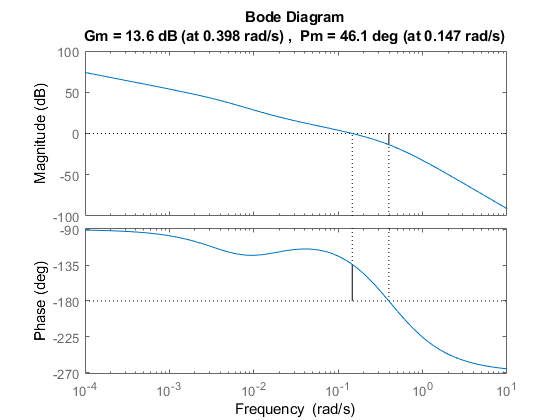

Gc=Kc*(1+T*s)/(1+T*beta*s);
margin(G*Gc)

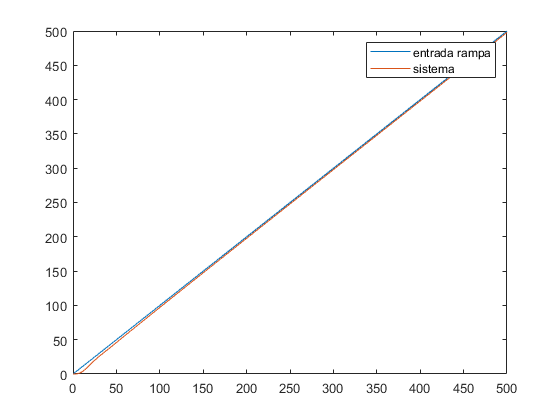

t=linspace(0,500,500);
R=step(1/s,t);
plot(t,R)
hold on
Y=step(1/s*feedback(G*Gc,1),t);
plot(t,Y)
hold off
legend('entrada rampa', 'sistema')
axis([0 500 0 500])

Kv=1/(max(R)-max(Y))

Kv = 0.4995

### c) Compare as respostas.

Por algum motivo, não foi possível atender ao requisito de margem de fase com o compensador de avanço. Já com o compensador de atraso, os requisitos de margem de fase e de $K_v$ foram facilmente atendidos.